# QUICK TEST

Simple code to test that everything runs smoothly.

clear; close all; clc

addpath ..\..\examples\Mechanical\mpc
run ..\..\startup.m

              _____ _____     
  _   _  __ _|  ___| ____|___ 
 | | | |/ _` | |_  |  _| / __|
 | |_| | (_| |  _| | |__| (__ 
  \__, |\__,_|_|   |_____\___|
  |___/       YetAnotherFEcode




## Base case (p=0)

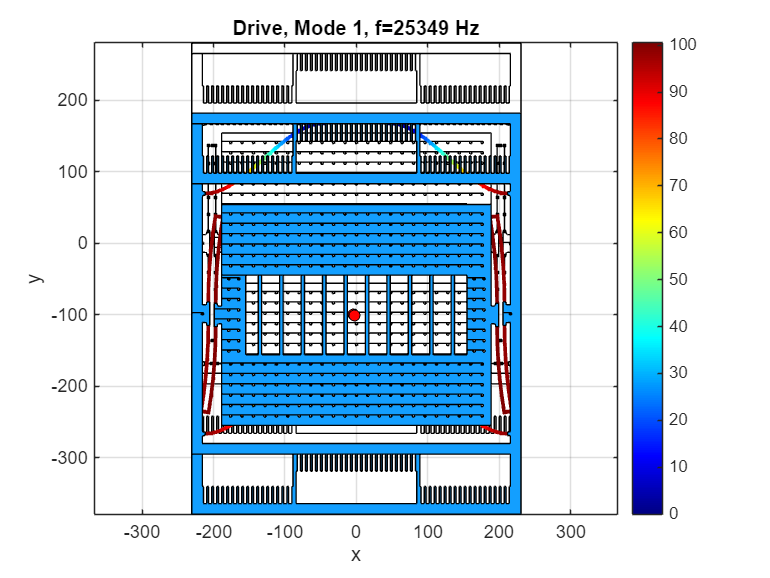

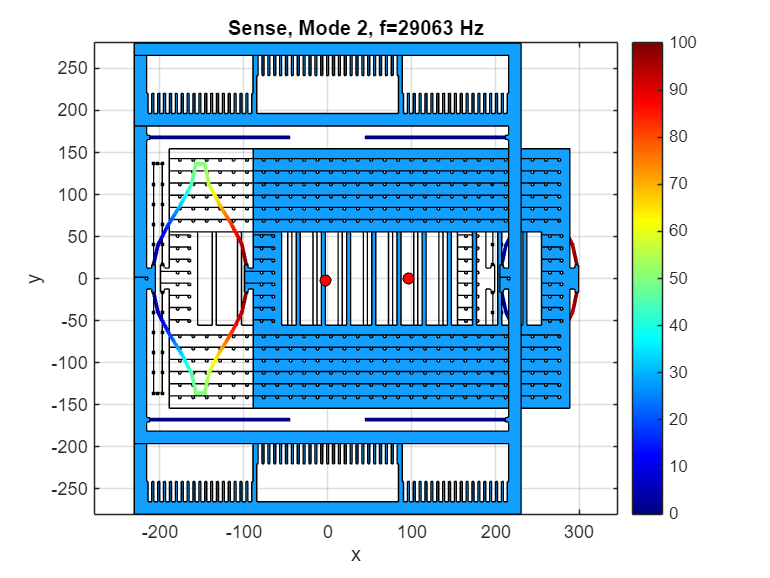

 mode: 1
 dof: 365 
 gamma = 1.32172e+12


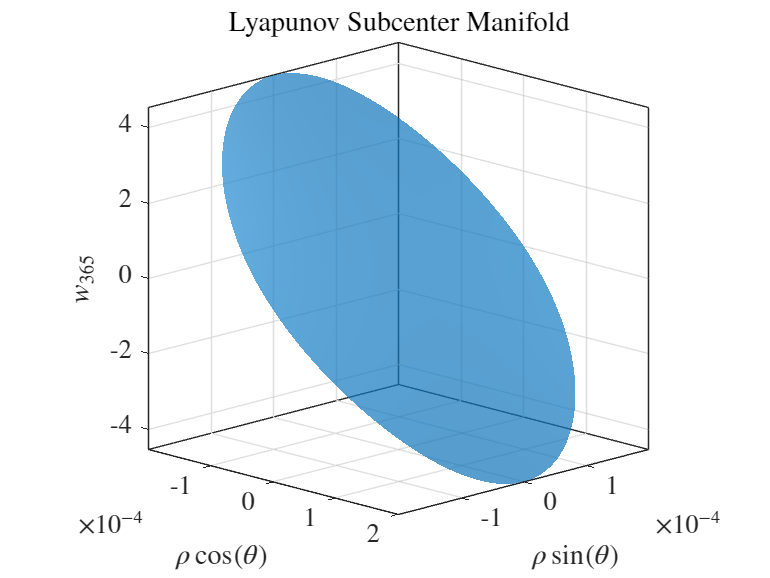

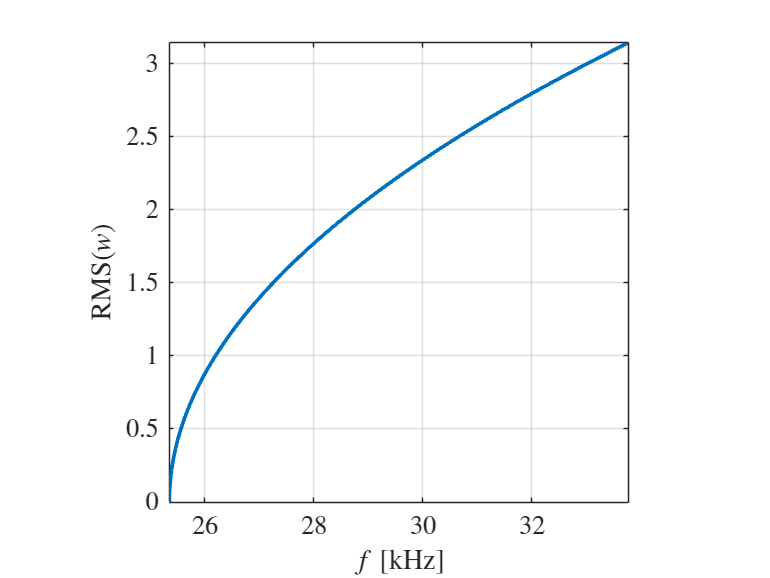

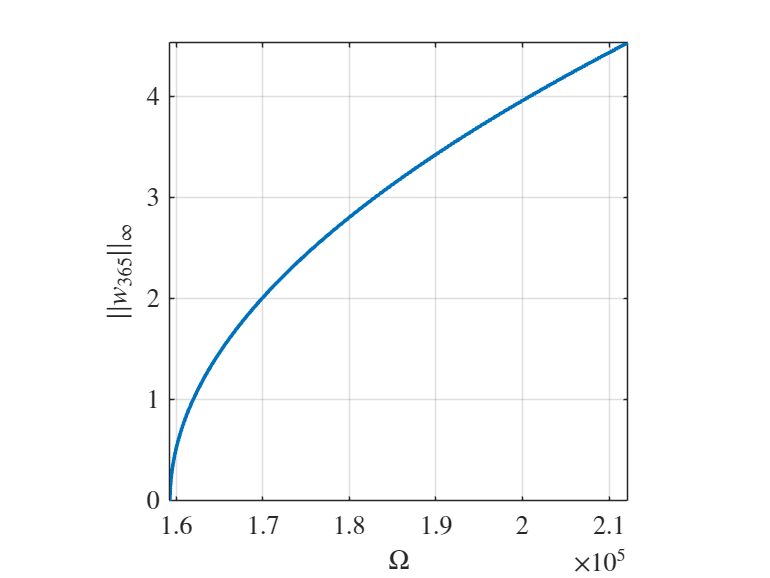

p = zeros(15,1);
obj = build_model(p*0);
[Omega, wBB_rms, wBB_infNorm] = analyze_system(obj);

## Check accuracy using SSMtool (v2.6)

 SSMTool (v2.6) added to path.

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 0
modal damping ratio for 2 mode is 0
modal damping ratio for 3 mode is 0
modal damping ratio for 4 mode is 0
modal damping ratio for 5 mode is 0
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+06 *
   0.0000 + 0.1593i
   0.0000 - 0.1593i
   0.0000 + 0.1826i
   0.0000 - 0.1826i
   0.0000 + 1.1441i
   0.0000 - 1.1441i
   0.0000 + 1.2100i
   0.0000 - 1.2100i
   0.0000 + 2.4113i
   0.0000 - 2.4113i
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     2     1
     3     1
     3     2
     4     2
     4     3
     5     3
     5     4
     6     4
     0     2
     1     2
     

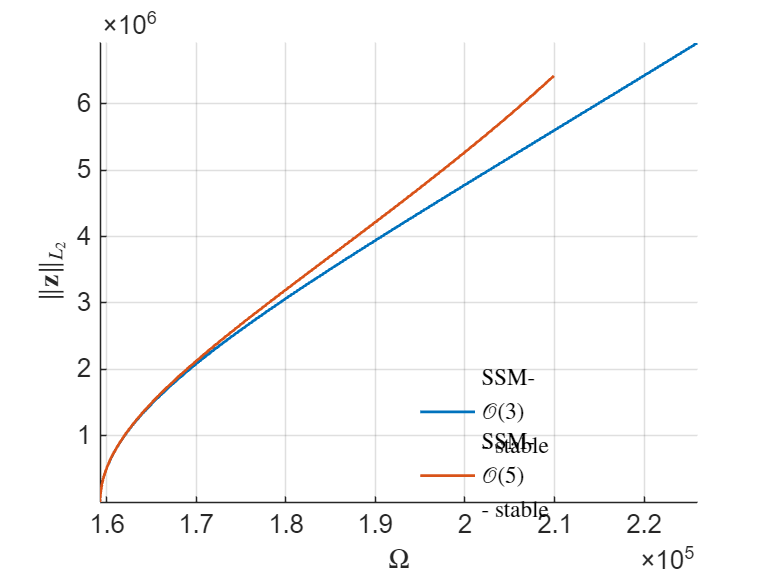

Total time spent on backbone curve computation = 00:00:03
 SSMTool (v2.6) removed from path.



order = [3 5];
imod = 1;
bb = verify_using_SSMtool(obj, order, imod);

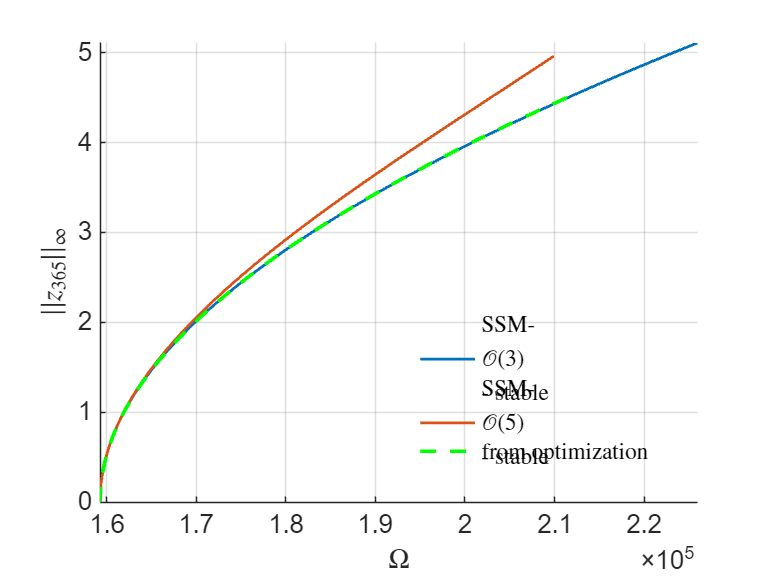

hold on;
plot(Omega, wBB_infNorm, 'g--', 'LineWidth',2,'DisplayName', 'from optimization')

## Frequency Response Curve

 SSMTool (v2.6) added to path.



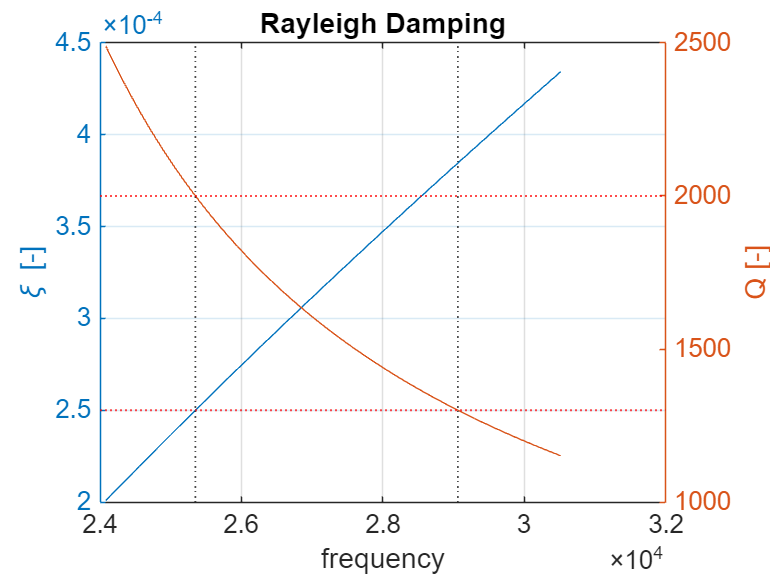

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.500000e-04
modal damping ratio for 2 mode is 3.846154e-04
modal damping ratio for 3 mode is 4.312384e-03
modal damping ratio for 4 mode is 4.566465e-03
modal damping ratio for 5 mode is 9.169993e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+06 *
  -0.0000 + 0.1593i
  -0.0000 - 0.1593i
  -0.0001 + 0.1826i
  -0.0001 - 0.1826i
  -0.0049 + 1.1441i
  -0.0049 - 1.1441i
  -0.0055 + 1.2100i
  -0.0055 - 1.2100i
  -0.0221 + 2.4112i
  -0.0221 - 2.4112i
No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 555
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5

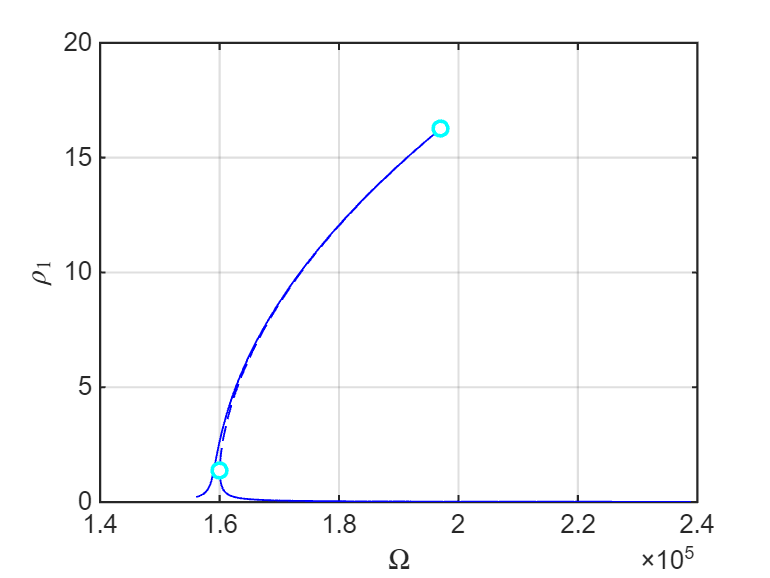

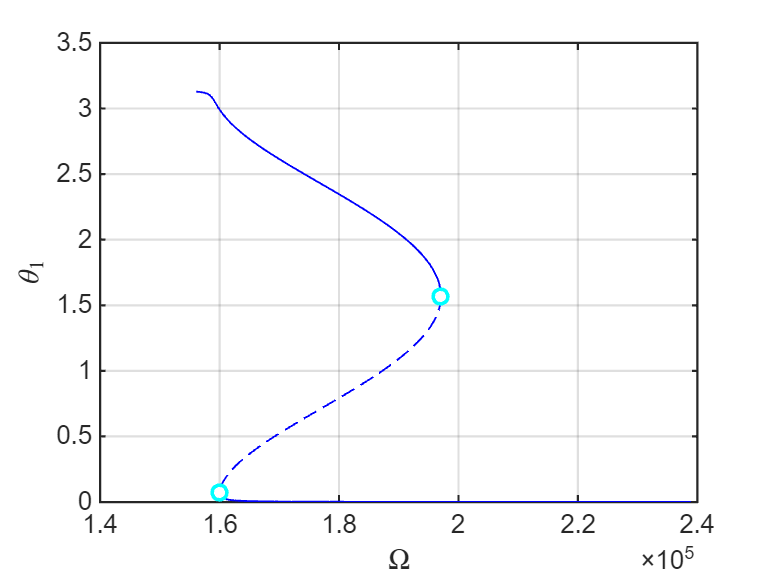

the forcing frequency 1.5609e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5640e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5673e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5705e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5734e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5761e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5786e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5810e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5832e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequency 1.5853e+05 is nearly resonant with the eigenvalue -3.9818e+01 + i1.5927e+05
the forcing frequenc

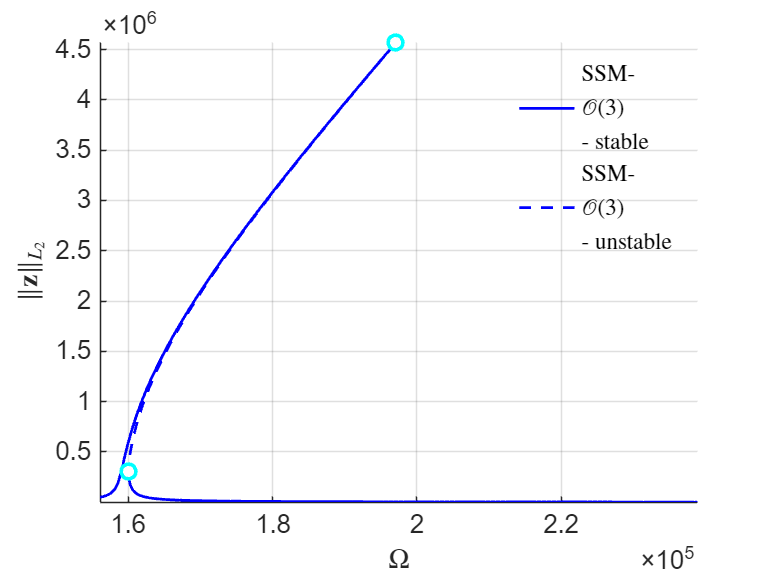

varargout = 1×1 cell array
    {1×1 struct}

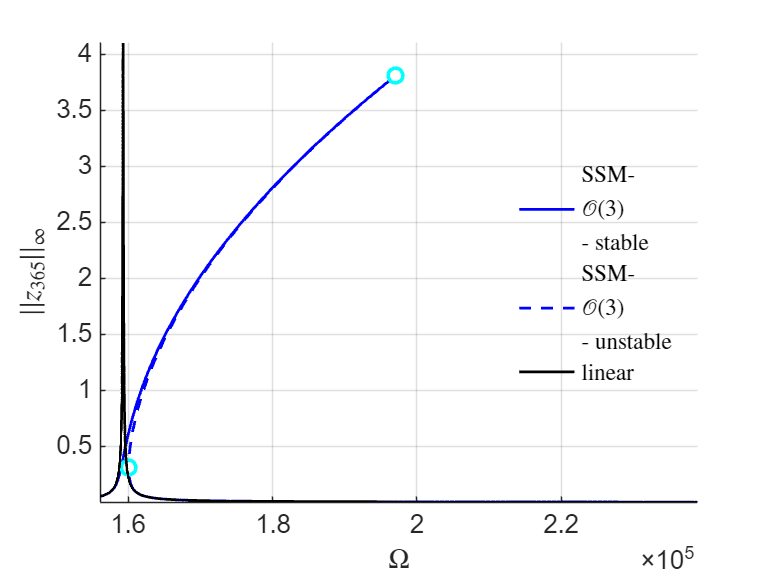

Elapsed time is 43.824665 seconds.
 SSMTool (v2.6) removed from path.



order = 3;
epsilon = 0.42; % [uN] force amplitude
Qfactor = [2000 1300];
omegaRange_norm = [0.98 1.5];
FRC = FRC_using_SSMtool(obj,order,imod,Qfactor,epsilon,omegaRange_norm);